# Atividades sobre gráficos de resposta em frequência 

# e estabilidade relativa.

## Sistemas Realimentados

**Atenção:** Este live script foi feito no Matlab versão 2019b. 

Em versões mais antigas os botões e sliders podem não funcionar.

**Critério de estabilidade de Nyquist**

Seja a FT $G(s)$e seu correspondente gráfico polar ou de Nyquist. 

O critério simplificado de Nyquist é dado por:


$$\phi=(Z_d-P_d-\frac{P_\omega}{2})$$


Onde:

$\phi:$ângulo feito pelo gráfico polar em torno do ponto -1 quando $\omega$ varia de infinito a zero.

$P_d:$polos de G(s) no semi-plano direito 

$P_\omega:$polos de G(s) na origem

$Z_d:$polos de malha fechada no semi-plano direito ( é o que se quer saber)

Os 3 primeiros ($\phi,P_d,P_\omega$) são dados de malha aberta, enquanto $Z_d$ é um dado de malha fechada.

Para estabilidade, $\phi$ deve ser negativo ($Z_d=0$).

Exemplo de medição do ângulo $\phi$ para $G(s)=\frac{K}{s(s+1)$.

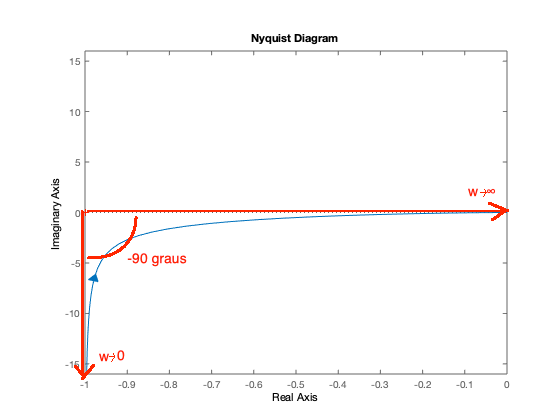

## 1. Verificar a estabilidade usando o critério de Nyquist com gráficos polares (ou de Nyquist).

1.1 Para que valores de ganho esta FT é estável?

g=tf([1 100],poly([0 -1 -10]))

g =
 
        s + 100
  -------------------
  s^3 + 11 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


polos=pole(g)

polos =      0
   -10
    -1


Função tem Pd=0 e Pw=1/2

Toda vez que não tem polo no SPD e tem um polo na origem, para a estabilidade, phi = -90º

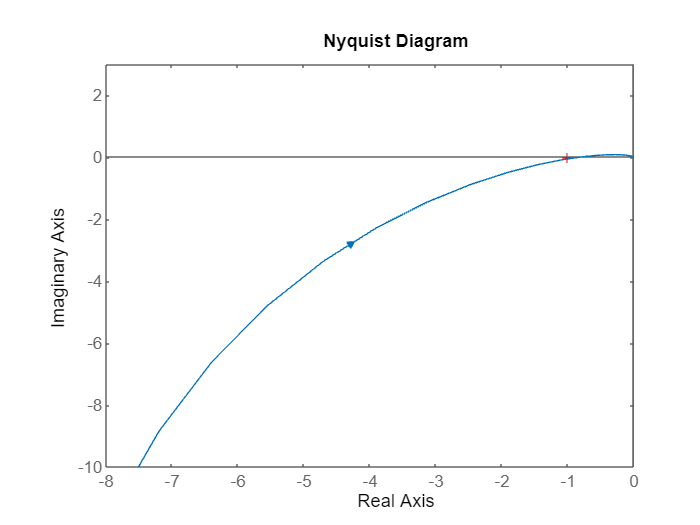

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-10 3]);

Resposta: É estável, porque phi = -90º

O valor do ganho K que deixa o sistema instável é o valor que faz com que a FT envolva o ponto -1

Visualizar com Bode:

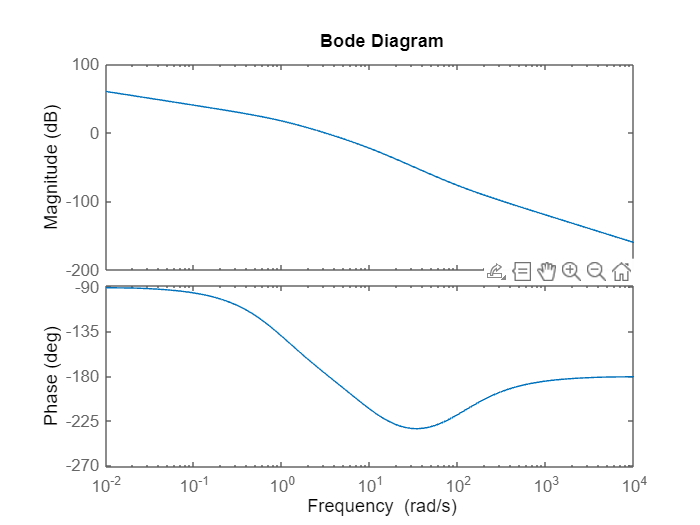

bode(g)

Ver a magnitude para -180º:

- se for maior que 0db, está envolvendo o -1 e é instável

- se for menor que 0db, não está envolvendo o -1 e é estável

1.2 Para que valores de ganho esta FT é estável?

g=tf([1 10],[1 0 0])

g =
 
  s + 10
  ------
   s^2
 
Continuous-time transfer function.
Model Properties


polos=pole(g)

polos =      0
     0


FT tem Pd=0 e Pw=1

Portanto, para a estabilidade, phi = -180º

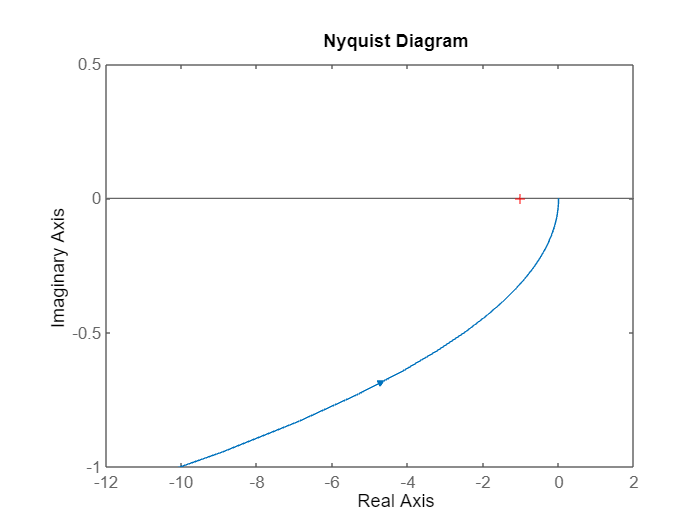

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-1 0.5]);

Resposta: Instável, pois phi = -90º

Pelo Bode:

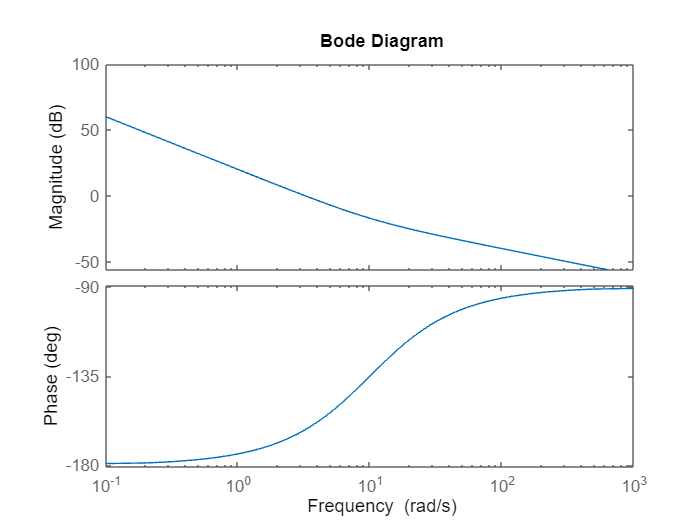

bode(g)

Sempre instável (para todo K)

1.3 Para que valores de ganho esta FT é estável?

g=tf(0.5*[1 3],[1 -1 0])

g =
 
  0.5 s + 1.5
  -----------
    s^2 - s
 
Continuous-time transfer function.
Model Properties


poles=pole(g)

poles =      0
     1


Pd = 1 e Pw = 1-2, portanto, para a estabilidade, phi = -270º

Multiplicar por um ganho faz o ponto passar à esquerda do -1 ficando estável

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');
ylim([-3 20]);

1.4 Obter o faixa de ganhos K para estabilidade do sistema abaixo.

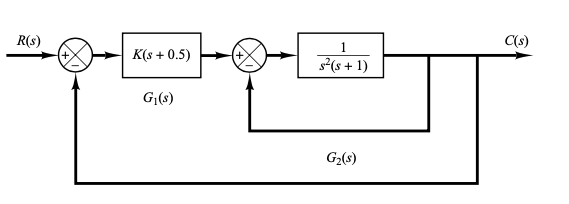

g=tf([1 0.5],[1 1 0 1])

g =
 
     s + 0.5
  -------------
  s^3 + s^2 + 1
 
Continuous-time transfer function.
Model Properties


polos=pole(g)

polos =   -1.4656 + 0.0000i
   0.2328 + 0.7926i
   0.2328 - 0.7926i


Pd = 2 e Pw =0

Para a estabilidade, phi = -360º 

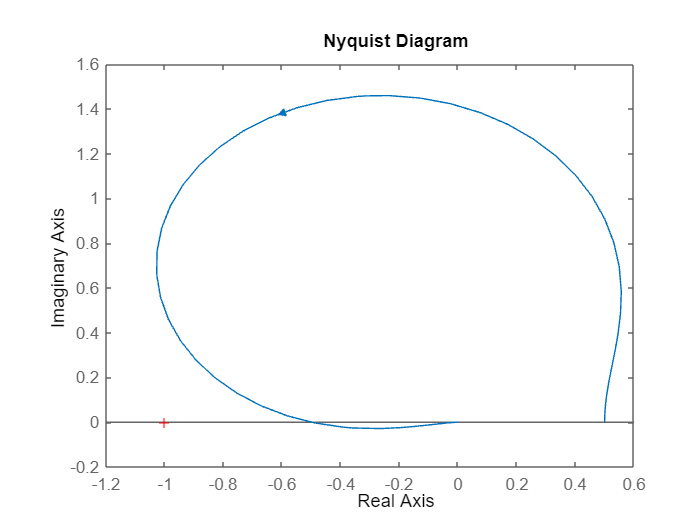

figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');

Resposta: Multiplicar por um ganho K que envolva o -1 (K>=2 pois 2*-0,5 = -1  ponto onde está cruzando o eixo real)

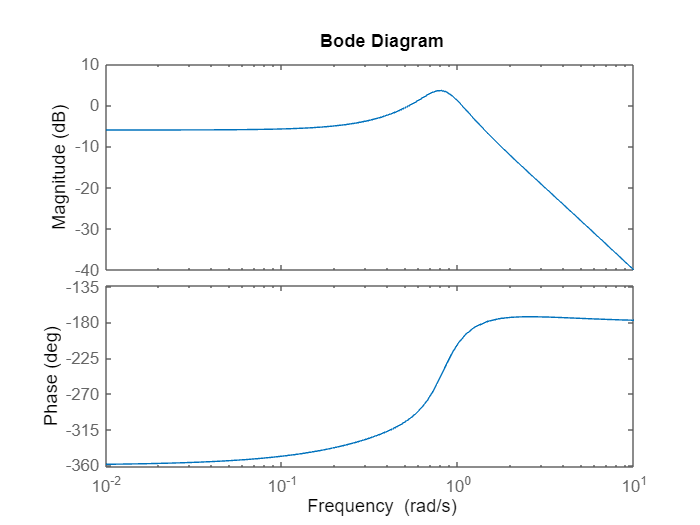

bode(g)

Somar aprox 5db? -> não entendi

1.4 Seja o gráfico de Nyquist mostrado abaixo para uma FT G(s) com 2 polos no SPD, 1 polo na origem, e 1 zero no SPE. Verifique se este sistema é estável em malha fechada.

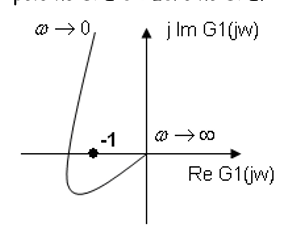

1.5 Seja o gráfico de Nyquist de G(s) mostrado abaixo, desenhado para K=1. Sabendo tratar-se de um sistema de fase mínima, obtenha os valores de K para estabilidade.

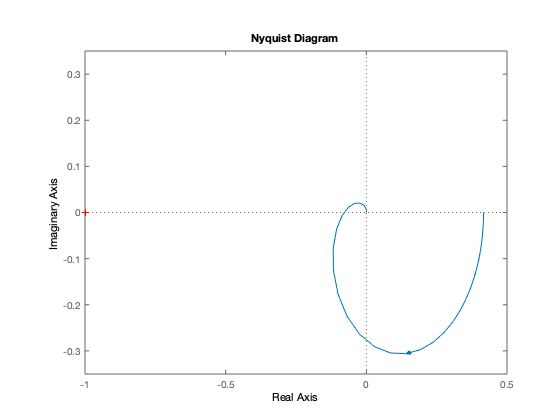

Resposta:

## 2. Estabilidade relativa via gráficos de Bode

2.1 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(1,poly(-[0 1 10]));
figure;
bode(g);grid;

Resposta:

2.2 Verifique qual a nova margem de ganho e fase se um ganho K=10 for adicionado à FT.

g=tf(10,poly(-[0 1 10]));
figure;
bode(g);grid;


Resposta:

2.3 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(0.5*[1 3],[1 -1 0]);
figure;
bode(g);grid;

2.4 Verifique a margem de fase e de ganho do sistema abaixo. 

g=tf(5,poly(-[1 10]));
figure;
bode(g);grid;


2.5 Seja $G(s)=10\frac{1/p+1}{s(s+1)(s+10)}$ . Avalie o efeito da localização do zero nas margens de fase e ganho.

Relacione estas mudanças com a resposta ao degraus.

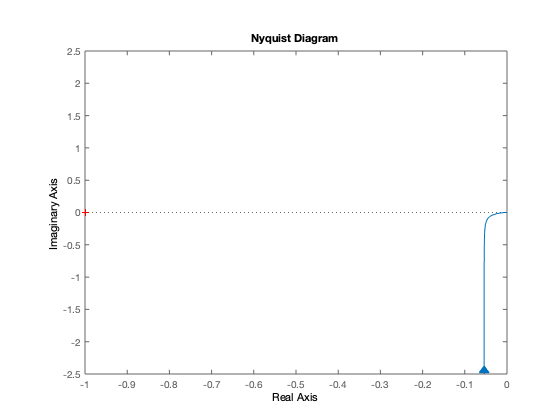

p=0; % escolher um valor de p entre 0 e 100
if p==0
g=tf(K,poly(-[0 1 10]));
else
    g=tf(K*[1/p 1],poly(-[0 1 10]));
end
figure;h=nyquistplot(g);set(h,'ShowFullContour','off');

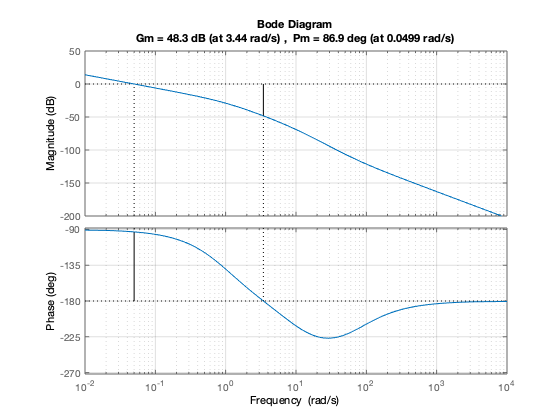

figure;margin(g);grid;

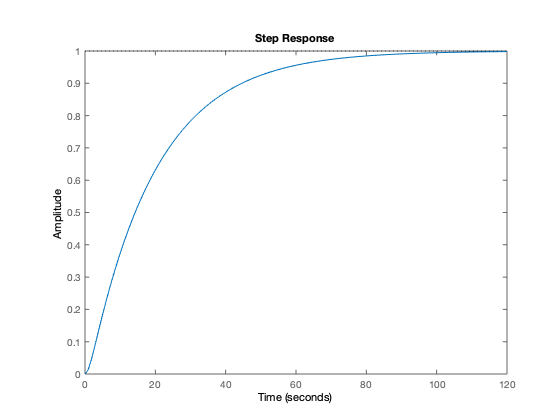

figure;step(feedback(g,1));

2.6 Verifique a estabilidade relativa do sistema cujo gráfico de Bode é mostrado abaixo

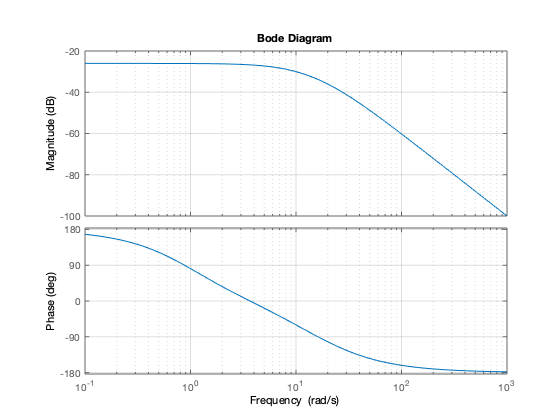

Resposta:

## 3. Sistemas com atraso de tempo

3.1  Obter o faixa de ganhos K para estabilidade do sistema cuja FT de malha aberta é $G(s)=\frac{Ke^{-0.8s}}{s+1}$.

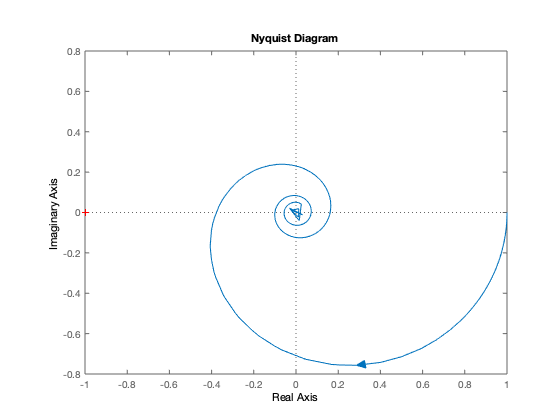

g=tf(1,[1 1], 'InputDelay',0.8);
figure;
h=nyquistplot(g);
set(h,'ShowFullContour','off');

3.1 Avaliar o efeito do atraso de tempo na estabilidade relativa do sistema dado por $G(s)=\frac{Ke^{-ds}}{s+1}$ para $K=0.5$ e para $K=2$.

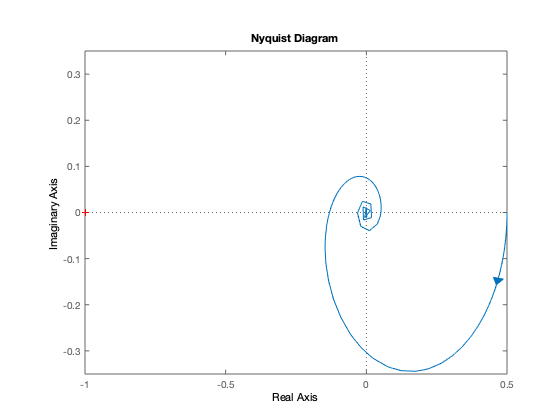

K=0.5; 
d=0; % Escolher um valor de d entre 0 e 1
g=tf(K,[1 1],'InputDelay',d);

figure;h=nyquistplot(g);set(h,'ShowFullContour','off');

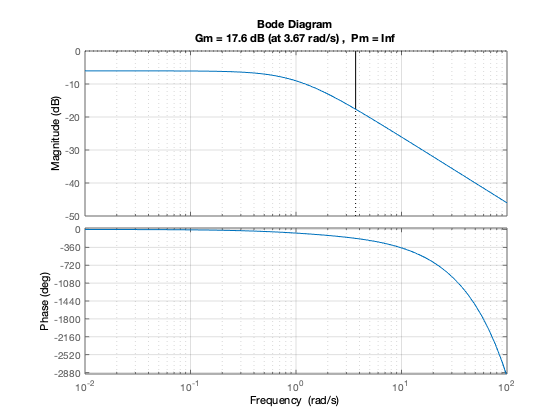

figure;margin(g);grid;

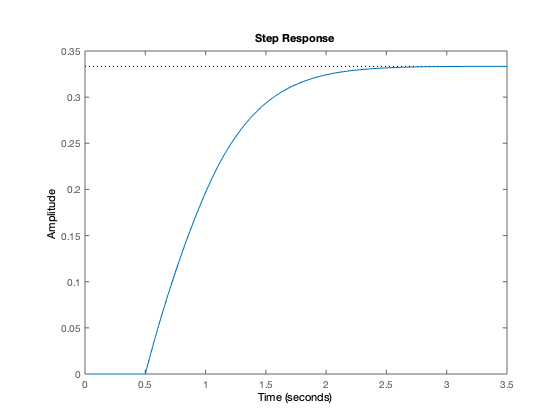

figure;step(feedback(g,1));